clear all
data = readtable("G20CrNi2Mo Bearing Steel Data_Zhao.xlsx");

%data.Properties.VariableNames
%unique(data.ContactStressAmplitude_MPa_);
%groupcounts(data, "ContactStressAmplitude_MPa_"); 

stress_data = data.ContactStressAmplitude_MPa_;
life_data = data.NumberOfCycles;

# **Plot the raw data**

figure
scatter(life_data,stress_data,"black",'filled');
hold on
set(gca,'xscale','log') % from MATLAB community
xlabel('Number of Cycles to failure')
ylabel('Stress Amplitude (MPa)');
title('Fatigue Test Data for G20CrNiMo Bearing Steel');
grid on 

# **Find the slope coefficient and intercept corresponding to 50% quantile **

fatigue_data = [stress_data life_data]; % stores the stress amplitude and matching fatigue life together in a single array

% transform to log-log 
log_stress_data = log10(stress_data);
log_life_data = log10(life_data);

% matlab checks because of issues with quantile reg
%size(log_stress_data)
%size(log_life_data)
%[min(log_stress_data) max(log_stress_data)]
%[min(log_life_data) max(log_life_data)]
%corrcoef(log_stress_data, log_life_data)

% linear quantile regression for 50% quantile, which gives B50 (distribution-less)
B50_model = fitrqlinear(log_stress_data, log_life_data, Quantiles=0.50, Lambda=0,Standardize=true, BetaTolerance=1e-6) % order matters here, the predictor is the log-stress and the response is log-life

B50_model =   RegressionQuantileLinear
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                     Beta: -0.3828
                     Bias: 7.7525
                Quantiles: 0.5000



slope_coefficient = B50_model.Beta

slope_coefficient = -0.3828

intercept = B50_model.Bias

intercept = 7.7525

B50_model.ConvergenceInfo % required because of convergence issues, had to include standardize = true for proper run

ans = struct with fields:
                  Lambda: 0
               Objective: 0.2050
          IterationLimit: 1000
           NumIterations: 8
            GradientNorm: 3.6097e-18
       GradientTolerance: 1.0000e-06
    RelativeChangeInBeta: 4.2730e-04
           BetaTolerance: 1.0000e-06
         TerminationCode: 2
       TerminationStatus: {'Tolerance on gradient satisfied.'}
                 History: []
                 FitTime: 0.0581



% generate the B50 Y points 
B50_predictions = predict(B50_model, log_stress_data); % to ensure s-n curve matches up with data, due to standardise


# **Median S-N curve plots**

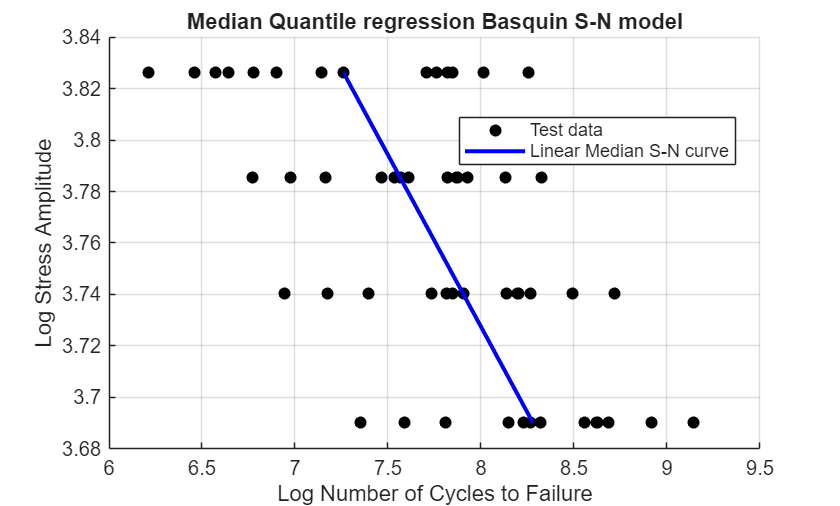

figure 
scatter(log_life_data, log_stress_data, "black", "filled");
hold on 
plot(B50_predictions, log_stress_data,'Color', 'b', 'LineWidth', 2)
xlabel('Log Number of Cycles to Failure');
ylabel('Log Stress Amplitude');
title('Median Quantile regression Basquin S-N model');
legend('Test data','Linear Median S-N curve','Location','best');
grid on
hold off


% convert to regular S-N plot from log-log formulation
% convert predicted log-life values back to cycles for the S-N plot by exponentiation
B50_life = 10.^B50_predictions; 

figure 
scatter(life_data,stress_data,"black",'filled'); 
hold on
plot(B50_life, stress_data, 'Color', 'g', 'LineWidth', 2)
set(gca,'xscale','log') % from MATLAB community
xlabel('Number of Cycles to failure')
ylabel('Stress Amplitude (MPa)');
title('S-N curve for G20CrNi2Mo Bearing Steel')
legend('Test data', 'Median S-N curve', 'Location', 'best')
grid on
hold off


# **Residual analysis **

e = log_life_data - B50_predictions; 
% compute the standard deviation of the residual at each stress level 
stress_levels = unique(stress_data); 
num_stress_levels = numel(stress_levels)

num_stress_levels = 4

residual_sigma = zeros(num_stress_levels, 1)

residual_sigma =      0
     0
     0
     0


residual_mu = zeros(num_stress_levels, 1)

residual_mu =      0
     0
     0
     0


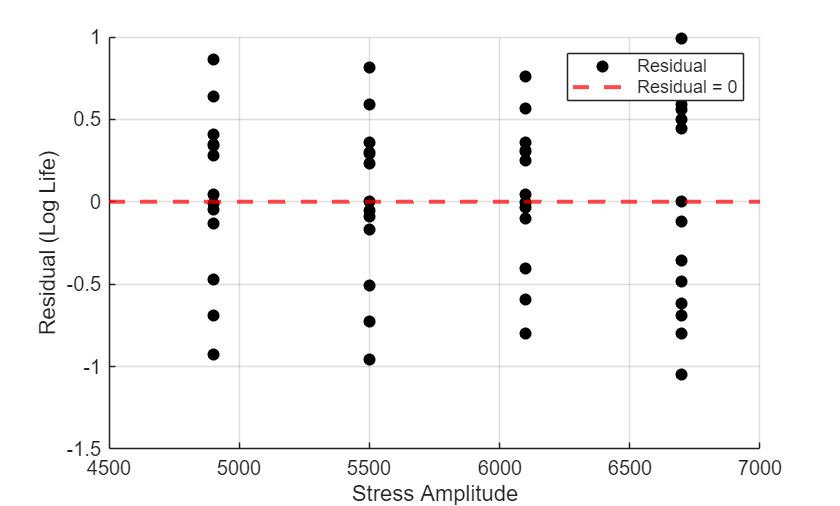

% plot residuals against log stress 
figure
scatter(stress_data, e, 'black', 'filled');
yline(0, '--r', 'LineWidth', 2);
xlabel('Stress Amplitude'); % come back and overlay another axis for log stress amplitude here
ylabel('Residual (Log Life)');
%title('Life scatter from Median S-N curve');
legend('Residual', 'Residual = 0')
grid on


% do some descriptive statistics on the whole dataset- finding the mean, median, standard deviations and maximum and minimum values 
e_mean = mean(e)

e_mean = 0.0165

e_median = median(e)

e_median = -4.5692e-04

e_std = std(e)

e_std = 0.5117

e_min = min(e)

e_min = -1.0492

e_max = max(e)

e_max = 0.9915


% calculate the standard deviations of data at each stress level
for i = 1:num_stress_levels 
    stressLevel = stress_levels(i);
    levelResiduals = e(stress_data == stressLevel);
    residual_sigma(i) = std(levelResiduals);
    residual_mu(i) = mean(levelResiduals);
end

residual_stats = table(stress_levels, round(residual_mu,3), round(residual_sigma,3), 'VariableNames', {'Hertzian contact stress amplitude (MPa)','Mean residual', 'Residual standard deviation'})

residual_stats = 4×3 table
    Hertzian contact stress amplitude (MPa)    Mean residual    Residual standard deviation
    _______________________________________    _____________    ___________________________

                     4900                          0.042                   0.495           
                     5500                              0                   0.491           
                     6100                          0.045                    0.43           
                     6700                         -0.021                   0.658           


writetable(residual_stats, 'Per stress level residual statistics.txt', 'Delimiter', '\t');
%residual_sigma 
%residual_mu 
% levene's test for equal residual variances across stress levels - null hypothesis is homoscedasticity 
[p, stats] = vartestn(e, stress_data,'TestType', 'LeveneAbsolute', 'Display', 'off');

fprintf('Levene test statistic: %.4f\n', stats.fstat);

Levene test statistic: 1.9004


fprintf('p-value: %.4f\n', p);

p-value: 0.1410


# **Checking for normal distribution to describe the residuals **

e_sorted = sort(e);
num_observations = numel(e_sorted);
observation_ranks = linspace(1, num_observations, num_observations);
X = e_sorted;

% for normal scatter -- lognormal fatigue life data 
F = ((observation_ranks - 0.3) / (num_observations + 0.4))';
Y_norm = norminv(F);
r_norm_matrix = corrcoef(X, Y_norm); % calculates correlation coeffiecient matrix
r_norm = r_norm_matrix(1, 2)

r_norm = 0.9885


fitted_line_norm = polyfit(X, Y_norm, 1);
reg_slope_norm = fitted_line_norm(1)

reg_slope_norm = 1.8836

intercept_slope_norm = fitted_line_norm(2)

intercept_slope_norm = -0.0311

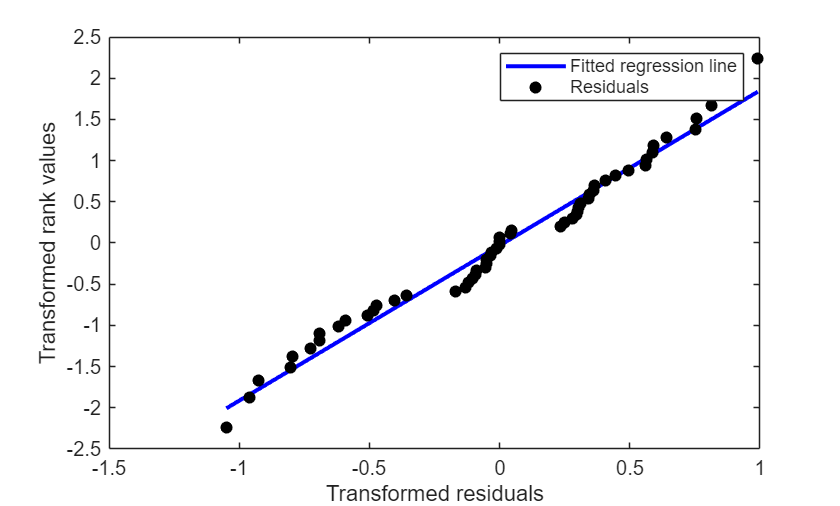

Y_fit_norm = (reg_slope_norm * X) + intercept_slope_norm;
% plot probability plots to see linearity of scatter 
figure 
plot(X, Y_fit_norm, 'Color', 'b', 'LineWidth', 2);
hold on 
scatter(X, Y_norm, 'filled', 'o', 'k');
xlabel('Transformed residuals');
ylabel('Transformed rank values');
legend('Fitted regression line', 'Residuals')
%title('Transformed CDF for residuals assuming normally distributed scatter')
hold off 


% GoF testing using Anderson-Darling assuming normally distributed residuals 
clear adtest 
[h_norm, p_value_norm, test_stat_norm, cv_norm] = adtest(e,"Distribution","norm")

h_norm = logical
   0


p_value_norm = 0.1284

test_stat_norm = 0.5791

cv_norm = 0.7412


% using AIC 
[params_norm] = mle(e, "distribution", "Normal")

params_norm =     0.0165    0.5071


nlogL_norm = normlike(params_norm, e)

nlogL_norm = 41.4350

loglike_norm = -nlogL_norm

loglike_norm = -41.4350

aic_norm = (2 * numel(params_norm)) - (2 * loglike_norm)

aic_norm = 86.8700

%aic_norm_matlab = aicbic(loglike_norm, numel(params_norm))

# **Checking for min. extreme value distribution to describe the residuals**

Y_ev = log(-log(1-F));
r_ev_matrix = corrcoef(X, Y_ev); % calculates correlation coeffiecient matrix
r_ev = r_ev_matrix(1, 2)

r_ev = 0.9770


fitted_line_ev = polyfit(X, Y_ev, 1);
reg_slope_ev = fitted_line_ev(1)

reg_slope_ev = 2.3404

intercept_slope_ev = fitted_line_ev(2)

intercept_slope_ev = -0.6011

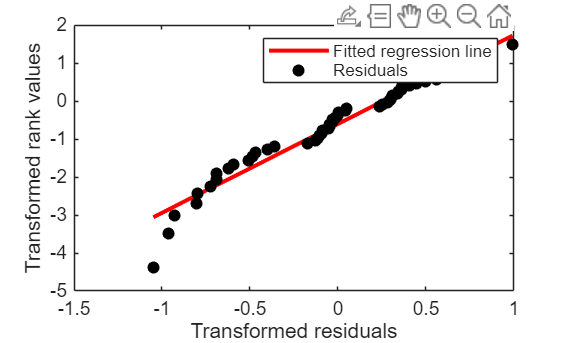

Y_fit_ev = (reg_slope_ev * X) + intercept_slope_ev;

figure 
plot(X, Y_fit_ev, 'Color', 'r', 'LineWidth', 2);
hold on 
scatter(X, Y_ev, 'filled', 'o', 'k');
xlabel('Transformed residuals');
ylabel('Transformed rank values');
legend('Fitted regression line', 'Residuals')
%title('Transformed CDF for residuals assuming extreme value distributed scatter')
hold off 


% GoF testing using Anderson_Darling assuming ev distributed residuals 
clear adtest 
[h_ev, p_value_ev, test_stat_ev, cv_ev] = adtest(e,"Distribution","ev")

h_ev = logical
   0


p_value_ev = 0.2544

test_stat_ev = 0.4672

cv_ev = 0.7489


% using AIC 
[params_ev] = mle(e, "distribution", "Extreme Value")

params_ev =     0.2630    0.4483


nlogL_ev = evlike(params_ev, e)

nlogL_ev = 41.8557

loglike_ev = -nlogL_ev

loglike_ev = -41.8557

aic_ev = (2 * numel(params_ev)) - (2 * loglike_ev) % aic formula -- aicbic needs econometrics toolbox - this is also more clear

aic_ev = 87.7113


h = [h_norm h_ev]';
p_value = [p_value_norm p_value_ev]';
test_stat = [test_stat_norm test_stat_ev]';
cv = [cv_norm cv_ev]';
aic = [aic_norm aic_ev]';
fatigue_mdl = ["2P Lognormal" "2P Weibull"]';

testres = table(fatigue_mdl, h, p_value, test_stat, cv, aic) 

testres = 2×6 table
     fatigue_mdl        h      p_value    test_stat      cv        aic  
    ______________    _____    _______    _________    _______    ______

    "2P Lognormal"    false    0.12841     0.57914     0.74123     86.87
    "2P Weibull"      false    0.25443     0.46725     0.74894    87.711


mu_norm = params_norm(1);
sigma_norm = params_norm(2); % the mean and s.d estimates for the normal distribution 
mu_ev = params_ev(1);
sigma_ev = params_ev(2); % location and scale parameter estimates for ev distribution 
residscatter_norm = norminv(0.01, mu_norm, sigma_norm)% finds the residual scatter associated with 99% PoS for normal model (fatigue life is lognormally distributed)

residscatter_norm = -1.1632

residscatter_ev = evinv(0.01, mu_ev, sigma_ev) % above, but for ev (fatigue life follows 2P weibull distribution)

residscatter_ev = -1.7993


% should have negative values for residscatter above because B1 curve is below B50
logB1_life_norm = B50_predictions + residscatter_norm;
logB1_life_ev = B50_predictions + residscatter_ev; % shifts the B50 curve down for each observation in log-log space

% transforming back to S-N, i.e. number of cycles to failure
B1_life_norm = 10 .^ logB1_life_norm; % remember element-wise operation for matrix
B1_life_ev = 10 .^ logB1_life_ev;

% plotting of 99% PoS and median S-N curve 


figure 
scatter(life_data,stress_data,"black",'filled'); 
hold on
plot(B50_life, stress_data, 'Color', 'g', 'LineWidth', 2)
plot(B1_life_norm, stress_data, 'Color', 'b', 'LineWidth', 2)
plot(B1_life_ev, stress_data, 'Color', 'r', 'LineWidth', 2)
set(gca,'xscale','log') % from MATLAB community
xlabel('Number of Cycles to failure')
ylabel('Hertzian Contact Stress Amplitude (MPa)');
%title('P-S-N curves for G20CrNi2Mo Bearing Steel')
legend('Test data', 'Median S-N curve', '99% PoS curve (2P Lognormal)', '99% PoS curve (2P Weibull)','Location', 'best')
grid on
hold off
